# **SENT - Simple Message Loopback**

This example demonstrates how the SENT protocol communicates with one Tx node and one Rx node, which are both on the same I/O module. You can test the basic functionality of the SENT protocol by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1x SENT Tx channel** and **1x SENT Rx channel  **     

- Connector cable from the I/O module to the terminal board

- Terminal board with one jumper wire

### Test Setup

In this example, data is sent from the SENT Tx channel to the SENT Rx channel. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins with jumper wires. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_SENT_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

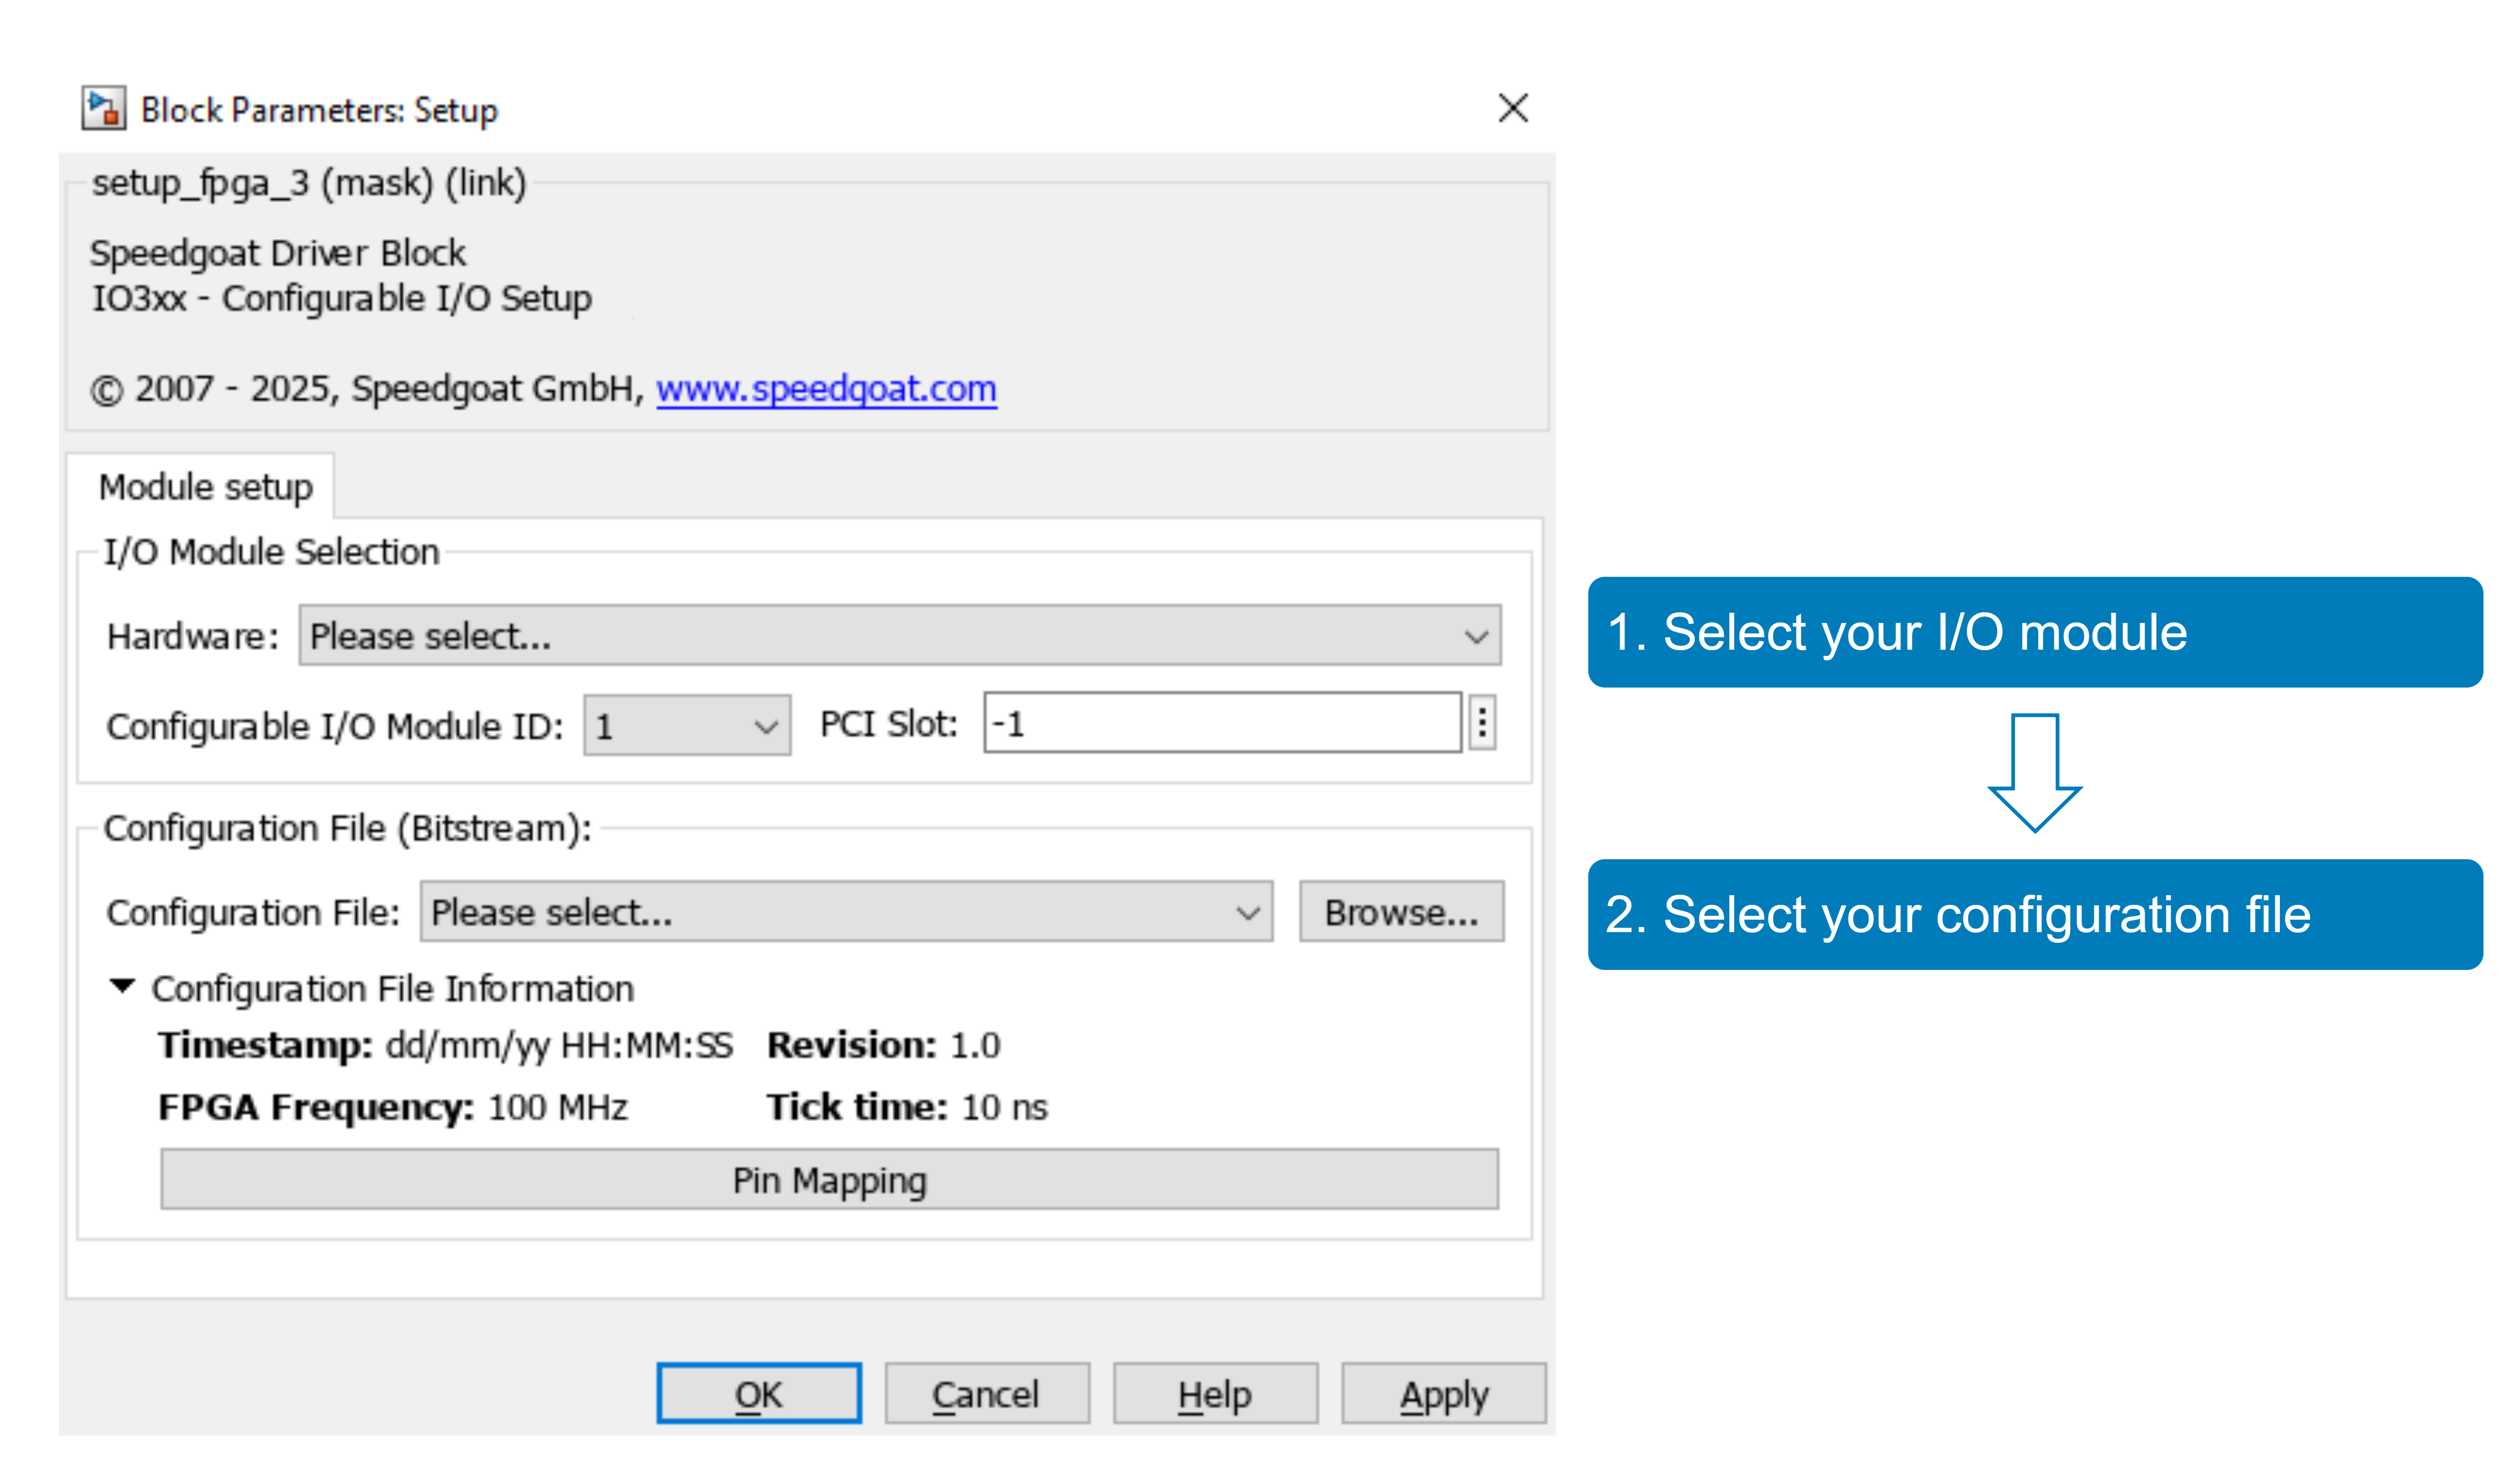

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In the model a counter is connected to the SENT Tx block for one fast message.

The fast message status depends on the counter;

- Counter 0...499     --> Status = 0

- Counter 500...749 --> Status = 1

- Counter 750...999 --> Status = 3

In this example, the SENT protocol is setup to also transfer enhanced serial messages. 

Note that the data format depends on the drop-down menu selection in the SENT tab of the SENT Tx block. For this model, the "Two 12-bit fast channels (H.1)" data format is used, therefore the signals must be converted with two Data Type Conversion blocks, that are placed between the source signals and the [SENT Transmit (Tx)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_tx_v1) block.

The fast messages and fast message status are received by the [SENT Receive (Rx)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_rx_v1) block and the signals are directly connected to a Simulink scope, where they can be inspected. Additionally, the fast message error status, fast message valid counter and fast message error counter can be inspected by a display.

The SENT Transmitter is running in **Sync Mode** which means that a single SENT frame is transmitted to the receiver in every model step. A pause-pulse is inserted between the SENT frames. The SENT Receiver is configured with **Enable Pause Pulse** set to true so the additional pause pulse does not lead to an error.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode',   'external')   % put model into External Mode
set_param(modelName, 'SimulationCommand','connect')    % connect with External Mode  

% Set Stop-Time to 8s and start the real-time application
tg.setStopTime(8);
tg.start;



### Check the Results

To check the loopback is working as expected, open the Simulink scope connected to the [SENT Rx](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sent_rx_v1) block. On the Scope, SENT_msg1 must display a counter signal, SENT_msg2 must display a sine wave and SENT_status must behave as described in the model behavior:

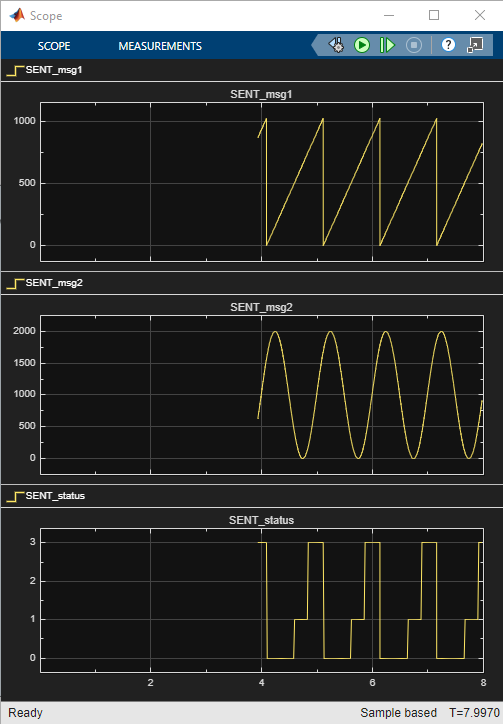

The displays showing "SENT_msg_errorStatus" and "SENT_msg_error_count" should be 0 (to indicate no error happened during data transmission).

## Additional References

- [SENT documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_sent)